clc
clear

imgPath = 'landscape.jpg';


## Image preprocessing

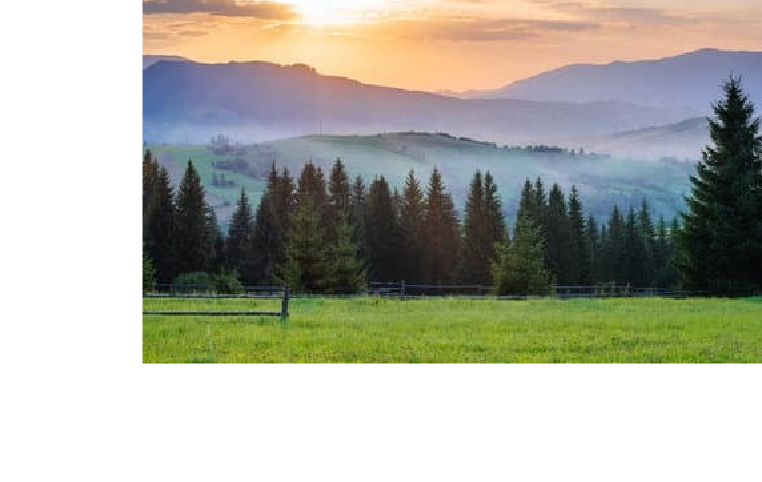

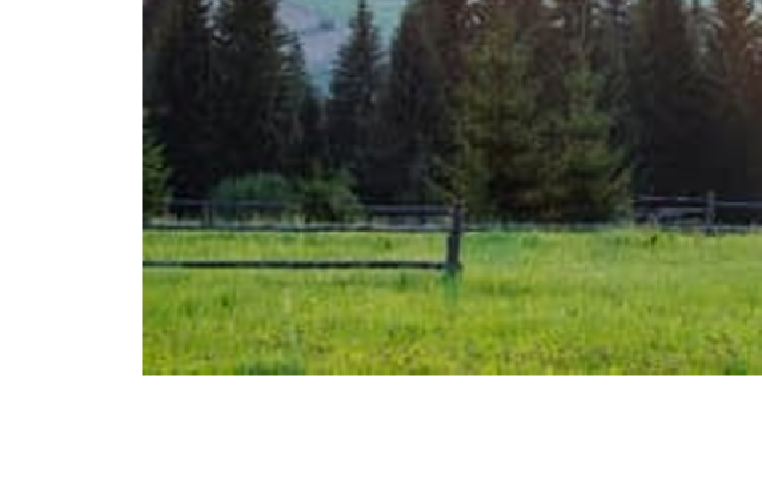

minW = 600;        % Min input width (px)
maxW = 3000;       % Max input width (px)
Wout = 1200;       % Output width (px)

img = im2double(imread(imgPath));
processedImg = preprocessImage(img, minW, maxW, Wout);

Ilab = rgb2lab(processedImg);


## Color palette generation & palette optimization

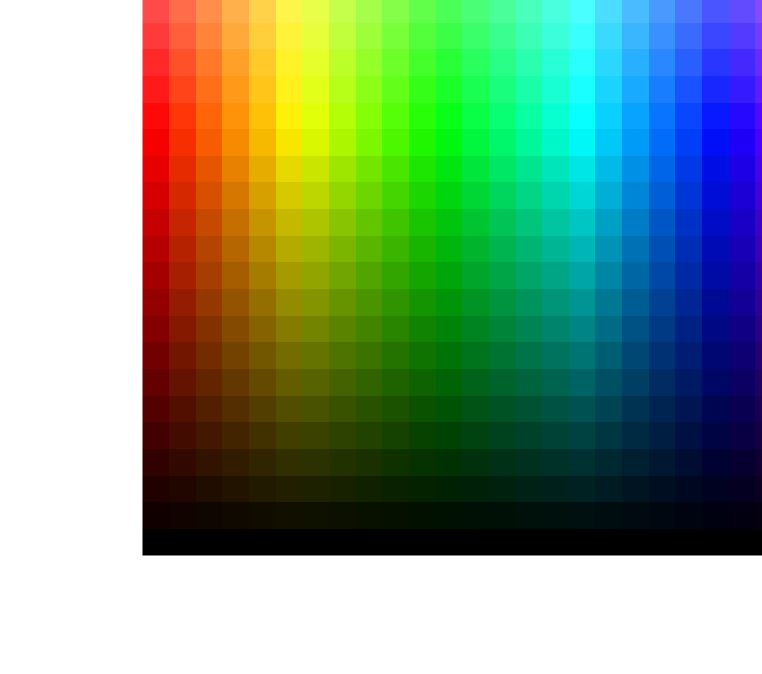

numColors= 32;              % Number of base colors
numShades = 32;             % Number of shades of the base colors

sampleQuantity = 50000;      % Number of samples for the optimized palette
numOptimizedBeads = 150;     % Number of colors in the optimized palette

[fullPaletteLab, paletteImage] = make_rainbow_palette(numColors, numShades);

figure;
imshow(imresize(paletteImage, 20, 'nearest')); 
title('Generated Rainbow Palette');

fprintf('Generated Palette (%d colors)', numColors * numShades)

Generated Palette (1024 colors)

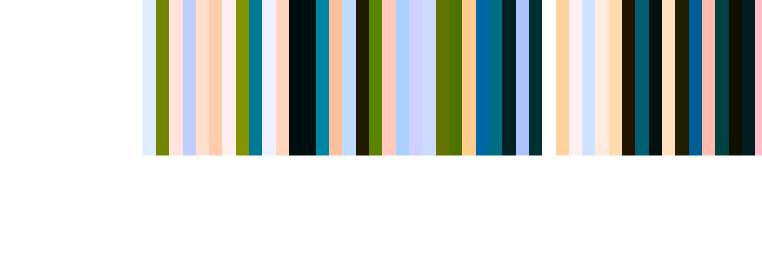


[optimizedPaletteLab, optPaletteSwatch] = optimize_palette(Ilab, fullPaletteLab, numOptimizedBeads, sampleQuantity);

figure;
imshow(imresize(optPaletteSwatch, 20, "nearest"));
title("Optimized palette");

fprintf('Optimized Palette (%d colors chosen from %d)', numOptimizedBeads, numColors * numShades)

Optimized Palette (150 colors chosen from 1024)

## Image reconstruction

maxSize = 64;              % The starting large triangle size (for the sky)
minSize = 8;               % The smallest triangle size (for the forest)
detailThreshold = 15;      % How much brightness variation triggers a split

[mosaicRGB, idxMap] = render_adaptive_triangle_mosaic(Ilab, optimizedPaletteLab, maxSize, minSize, detailThreshold);

Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or ALL functions to reduce operands to logical scalar values.

Error in render_adaptive_triangle_mosaic (line 69)
        if detailLevel > detailThreshold && currentSide > minSize * 1.1
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^


figure;
imshow(mosaicRGB);
axis image off;
title('Triangle bead mosaic');

## Evaluation

% TODO: Implement evaluation based on SSIM, SCIELAB